D = SessionData.RawEvents;
N = SessionData.nTrials;

IntDur = cell(N,1);
IntOn = cell(N,1);


for i = 1:N

    if any(~isfield(D.Trial{i}.Events, {'Port4In', 'Port4Out'}))
        continue;
    end
    cent_in = D.Trial{i}.Events.Port4In;
    cent_out = D.Trial{i}.Events.Port4Out;

    IntDur{i} = zeros(length(cent_out), 1);
    IntOn{i} = (cent_out - cent_in(1))';

    for j = 1:length(cent_out)
        cent_back = cent_in(find(cent_in>cent_out(j), 1));
        if isempty(cent_back)
            IntDur{i}(j) = 0;
        else
            IntDur{i}(j) = cent_back - cent_out(j);
        end
    end

    id = IntDur{i}>0.005 & IntDur{i}<0.5 & IntOn{i}<2 & IntOn{i}>0;
    IntOn{i} = IntOn{i}(id);
    IntDur{i} = IntDur{i}(id);

end


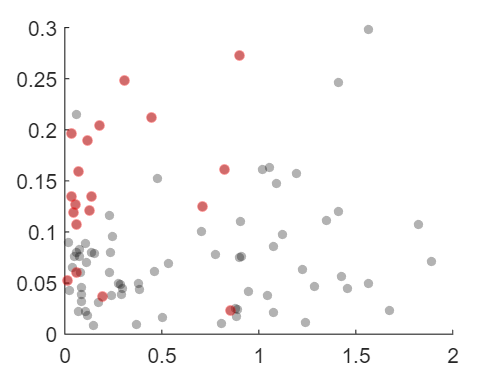

IntOnA = cell2mat(IntOn);
IntDurA = cell2mat(IntDur);

figure(); hold on;
scatter(IntOnA, IntDurA, 18, 'black', 'filled', 'o', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .3);
n_int_pre = 0;
n_pre = sum(SessionData.Custom.OutcomeCode==-1);
for i = 1:N
    if ~isempty(IntOn{i}) && SessionData.Custom.OutcomeCode(i)==-1
        j = find((IntOn{i}+IntDur{i})>SessionData.Custom.HoldDur(i), 1, 'first');
        scatter(IntOn{i}(j), IntDur{i}(j), 24, 'red', 'filled', 'o', ...
            'MarkerEdgeColor', 'none', ...
            'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .4);
        if IntDur{i}(j) < 0.2
            n_int_pre = n_int_pre + 1;
        end
    end
end
xlim([0 2]); ylim([0 .3]);


sum(IntDurA>0.1) / N

ans = 0.2883

sum(IntDurA>0.2) / N

ans = 0.0991

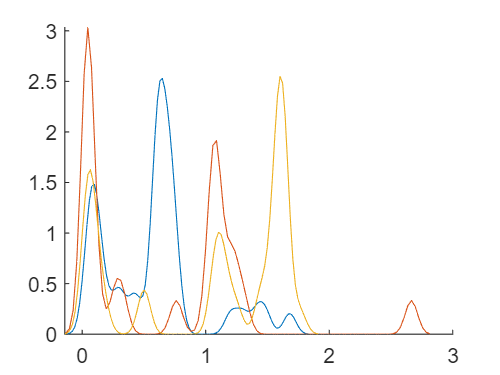

figure(); hold on;
ksdensity(SessionData.Custom.HoldDur(SessionData.Custom.FP==.5), 'bandwidth', 0.05)
ksdensity(SessionData.Custom.HoldDur(SessionData.Custom.FP==1), 'bandwidth', 0.05)
ksdensity(SessionData.Custom.HoldDur(SessionData.Custom.FP==1.5), 'bandwidth', 0.05)